dir_input = 'C:\Users\rsarin\Google Drive\ArmEMG\Data\SEEDS\FeaturesSubj\';
fname_input = '-SEEDSfeatures'; %Tag for file name (follows subject name)
includedspeeds={'both','slow','fast'}; %cell array of all speeds
sp = 1 %speed we want to examine

sp = 1

subjectnumbers = 2 %total number of subjects we will examine. This is a temporary fix. I want Matlab to calculate this.

subjectnumbers = 2

s = 1

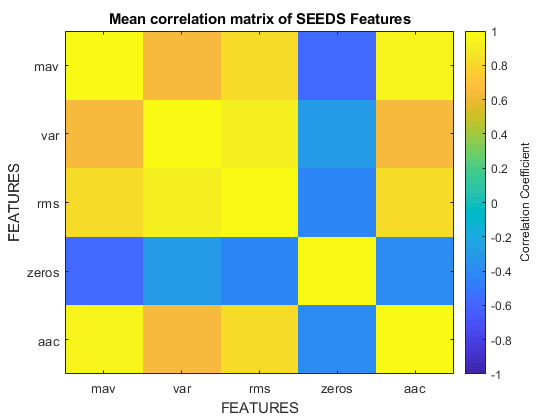

corr_mat = corr_mat(:,:,1) =

    1.0000    0.6333    0.8355   -0.5638    0.9420
    0.6333    1.0000    0.9330   -0.2899    0.6499
    0.8355    0.9330    1.0000   -0.4345    0.8201
   -0.5638   -0.2899   -0.4345    1.0000   -0.3835
    0.9420    0.6499    0.8201   -0.3835    1.0000


corr_mat(:,:,2) =

    1.0000    0.9206    0.9445   -0.6459    0.8904
    0.9206    1.0000    0.9548   -0.5386    0.8549
    0.9445    0.9548    1.0000   -0.6267    0.8587
   -0.6459   -0.5386   -0.6267    1.0000   -0.5257
    0.8904    0.8549    0.8587   -0.5257    1.0000


s = 2

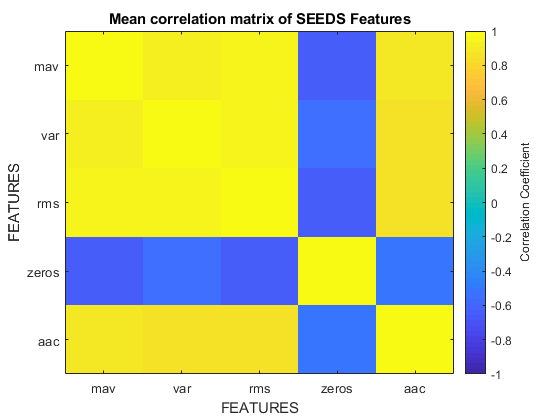

corr_mat = corr_mat(:,:,1) =

    1.0000    0.6333    0.8355   -0.5638    0.9420
    0.6333    1.0000    0.9330   -0.2899    0.6499
    0.8355    0.9330    1.0000   -0.4345    0.8201
   -0.5638   -0.2899   -0.4345    1.0000   -0.3835
    0.9420    0.6499    0.8201   -0.3835    1.0000


corr_mat(:,:,2) =

    1.0000    0.9206    0.9445   -0.6459    0.8904
    0.9206    1.0000    0.9548   -0.5386    0.8549
    0.9445    0.9548    1.0000   -0.6267    0.8587
   -0.6459   -0.5386   -0.6267    1.0000   -0.5257
    0.8904    0.8549    0.8587   -0.5257    1.0000



for s = 1:subjectnumbers %iterate through each subject
    s %this is to check if our loop is iterating or not
    figure %to ensure we don't delete our old figure each time the loop runs
    load(strcat(dir_input,'subj',num2str(s,'%02.f'),fname_input,'_speed',includedspeeds{sp},'.mat')) %load data for the subject
    corr_mat(:,:,s) = feat_corr(includedchannels, includedfeatures, traindata) %For each subject, call featureCorrelationFunc.m
end

meansubjcorrmat = mean(corr_mat,3) %average corr matrix across all subjects

meansubjcorrmat =     1.0000    0.7769    0.8900   -0.6048    0.9162
    0.7769    1.0000    0.9439   -0.4143    0.7524
    0.8900    0.9439    1.0000   -0.5306    0.8394
   -0.6048   -0.4143   -0.5306    1.0000   -0.4546
    0.9162    0.7524    0.8394   -0.4546    1.0000


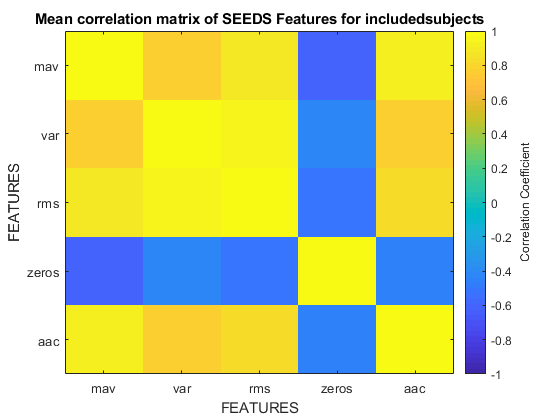

imagesc(meansubjcorrmat) %visual of mean subject correlation matrix 
title('Mean correlation matrix of SEEDS Features for includedsubjects');
xlabel('FEATURES');
xticks([1 2 3 4 5]); %temporary fix for #features - ideally would like to have name of feature as a tick. 
yticks([1 2 3 4 5]); %same as x tick
ylabel('FEATURES');
c = colorbar;
caxis([-1 1]); %limits for colorbar
c.Label.String = 'Correlation Coefficient';
xticks(1:length(includedfeatures));
xticklabels(includedfeatures);% Label x axis
yticks(1:length(includedfeatures));
yticklabels(includedfeatures);% Label y axis

    

%fds = fileDatastore('*_speedboth.mat', 'ReadFcn', @importdata) %finds all mat files in google drive
%fullFileNames = fds.Files % array of all mat files
%numFiles = length(fullFileNames) %counts num of mat files

Matlab wasn't recognizing the function call in the previous section, so I have pasted the function below as a temporary fix.

function [meancorrmat] = feat_corr(includedchannels, includedfeatures, traindata)

%find all channels and name them
names_ch = cellstr([repmat('_ch',length(includedchannels),1)  num2str(includedchannels') repmat('_',length(includedchannels),1) ]); 
names_ch = strrep(names_ch,' ','');%remove spaces in single digit channel names (ch_ 1 --> ch_1)

for n = 1:length(includedchannels) %iterate through channels
    idx_ch = contains(traindata.Properties.VariableNames,names_ch(n)); %find index where the channel exists in traindata
    predictorNames = traindata.Properties.VariableNames(idx_ch); %for each channel, take all features
    predictors = traindata(:,predictorNames); %extract data of predictorNames from traindata
    corr_mat(:,:,n) = corr(double(table2array(predictors))); %correlation matrix (size = #features x #features x #channels that we have looped through)
end
meancorrmat = mean(corr_mat,3); %mean of corr coeffs for all features across channels measured (size = #features x #features x 1)
imagesc(meancorrmat) %visual of mean correlation matrix 
title('Mean correlation matrix of SEEDS Features');
xlabel('FEATURES');
set(gca, 'XTick', 1:size(meancorrmat)); % center x-axis ticks
set(gca, 'YTick', 1:size(meancorrmat)); % center y-axis ticks
ylabel('FEATURES');
c = colorbar;
caxis([-1 1]); %limits for colorbar
c.Label.String = 'Correlation Coefficient';
xticks(1:length(includedfeatures));
xticklabels(includedfeatures);% Label x axis
yticks(1:length(includedfeatures));
yticklabels(includedfeatures);% Label y axis
end
